# Main con repulsive potentials

Configuration space

clear; close all; clc;
grid = Grid(10,10);
grid.setGoal([10,10]);

Obstacles and robot initial configuration

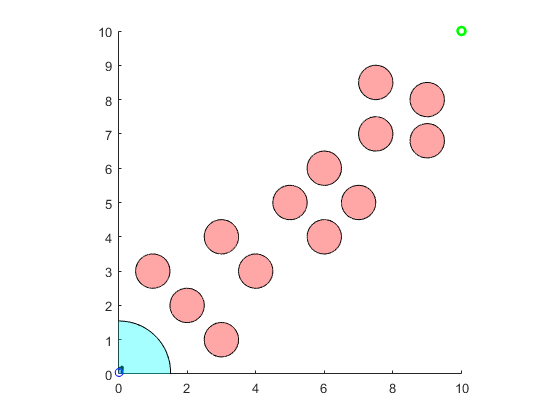

%Molti ostacoli
grid.addObstacle(Obstacle(2,2,[0;0])); %1
grid.addObstacle(Obstacle(4,3,[0;0])); %2
grid.addObstacle(Obstacle(3,1,[0;0])); %3
grid.addObstacle(Obstacle(5,5,[0;0])); %4
grid.addObstacle(Obstacle(6,6,[0;0])); %5
grid.addObstacle(Obstacle(7.5,8.5,[0;0])); %6
grid.addObstacle(Obstacle(7,5,[0;0])); %7
grid.addObstacle(Obstacle(7.5,7,[0;0])); %8
grid.addObstacle(Obstacle(1,3,[0;0])); %9
grid.addObstacle(Obstacle(3,4,[0;0])); %10
grid.addObstacle(Obstacle(9,8,[0;0])); %11
grid.addObstacle(Obstacle(9,6.8,[0;0])); %12
grid.addObstacle(Obstacle(6,4,[0;0])); %13

%Minimi locali
% grid.addObstacle(Obstacle(5,4,[0;0]));
% grid.addObstacle(Obstacle(7,4,[0;0]));


% r = ClassicalRobot(0.15,0.3,grid,0.05);
r = SwitchingRobot(0.15,0.3,grid,0.05);
r.start();